Pn = 90*10^3; % номинальная мощность
nn = 2955; % номинальная частота вращения (об/мин)
kpd = 93.5/100; % коэффициент полезного действия
cosfi = 0.93; % коэффициент мощности
Un = 380/sqrt(3); % фазное напряжение питания
In = 157; % линейный или фазный ток 
Mn = 291; % номинальный момент нагрузки
ks = 1.8; % кратность пускового момента ks =Ms/Mn
ki = 7; % кратность пускового тока ki =Is/In
lyambda = 2.7; % кратность максимального момента λ=Mm/Mn

m = 3; % число фаз
f = 50; % частота сети
zp = 1; % число пар полюсов

n1 = 60*f/zp % частота вращения магнитного поля статора(скорость циклического изменения магнитного потока статора, называется синхронной скоростью двигателя)

n1 = 3000

sn = (n1-nn)/n1 % величина номинального скольжения

sn = 0.0150

N = 3000; % синхронная частота вращения (об/мин)
J = 0.52; %
mass = 505; %
service_factor = 1.15; %

% Параметры схемы замещения
w1 = 2*pi*f  % Скорость вращения поля

w1 = 314.1593


%------
Rs = (Un*In*cosfi-Mn*w1/m/zp)/In^2

Rs = 0.0633

Rr0 = m*zp*Un^2*sn/w1/Mn

Rr0 = 0.0237

%------

mu_m = @(r2_) mu_m_calc(r2_,Rs,sn,lyambda,In,cosfi,Un,m,zp,w1,Mn);
Rr = fzero(mu_m,Rr0)

Rr = 0.0212


a = Rs/Rr

a = 2.9803

A = 1-2*a*sn*(lyambda-1)

A = 0.8480

s_m = sn*(lyambda+sqrt(lyambda^2-A))/A

s_m = 0.0927

x_ks = sqrt((Rr/s_m)^2-Rs^2)

x_ks = 0.2203

b = x_ks/((Rs+Rr/sn)^2+x_ks^2)

b = 0.0985

x_m = 1/((In*sqrt(1-cosfi^2))/Un-b)

x_m = 6.0783

x_s1 = x_ks/2;
x_s2 = x_ks/2;
I2_ = Un/sqrt((Rs+Rr/s_m)^2+(x_ks+x_m)^2)

I2_ = 34.7948

mu_m = m*zp*I2_^2*Rr/(w1*s_m*Mn)

mu_m = 0.0091


%------
h0 = 3;
mu_s = @(h) mu_s_calc(h,m,zp,Un,Rr,w1,Mn,Rs,x_s1,x_s2,ks);
h = fzero(mu_s,h0)

h = 2.4500


k_r = h*(sinh(2*h)+sin(2*h))/(cosh(2*h)-cos(2*h))

k_r = 2.4206

k_x = 3/2/h*(sinh(2*h)-sin(2*h))/(cosh(2*h)-cos(2*h))

k_x = 0.6229

mu_s = m*zp*Un^2*Rr*k_r/(w1*Mn*((Rs+Rr*k_r)^2+(x_s1+x_s2*k_x)^2))

mu_s = 1.8000

% Электрическая частота
w0_ = 2*pi*f;
w_ = 0.1*w0_:0.1*w0_:w0_;
% Механическая частота
w_mech0 = 2*pi*f/zp;
w_mech = 0.1*w_mech0:0.1*w_mech0:w_mech0;

% Индуктивность обмоток
Ls = (x_s1+x_m) / w0_;
Lr = (x_s2+x_m) / w0_;
Lm = x_m / w0_;
% изменяющиеся индуктивные сопротивления рассеяния 
x_s = Ls * w_;
x_r = Lr * w_;
x_m = Lm * w_;

Ku = Lr/(Ls*Lr - Lm^2);
Ki = (Rs*Lr^2 + Lm^2*Rr)/(Ls*Lr^2 - Lm^2*Lr);
K1 = Lm*Rr/(Ls*Lr^2 - Lm^2*Lr^2);
K2 = Lm/(Ls*Lr - Lm^2);
K3 = Lm*Rr/Lr;
K4 = Rr/Lr;

Mn_flag = 1;
Mn_coef = 0.5;
Tmdl = 10;
w_slope = 100

w_slope = 100

M_mech_sim = out.mechanic.Data(:,1); 
w_mech_sim = out.mechanic.Data(:,2) * 30/pi;
t = out.mechanic.Time;
Ia = out.electric.Data(:,1);
Ib = out.electric.Data(:,2);

u_a = out.U.Data(:,1);
u_a = [t u_a];
u_b = out.U.Data(:,2);
u_b = [t u_b];
u_c = out.U.Data(:,3);
u_c = [t u_c];

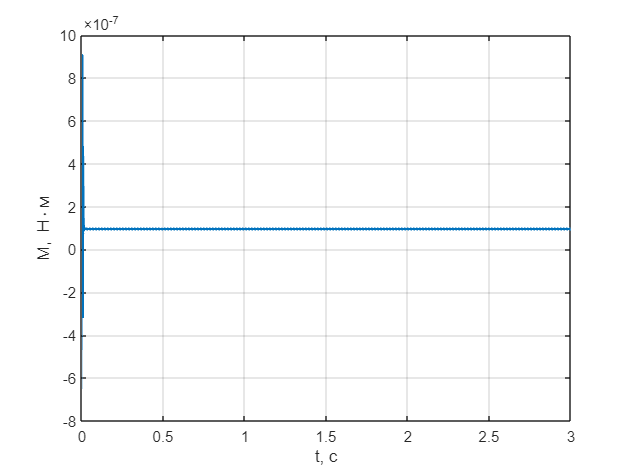

figure()
plot(t, M_mech_sim, 'LineWidth',2);
grid on
xlabel('t, c');
ylabel('M, Н\cdotм');
xlim([0 3])

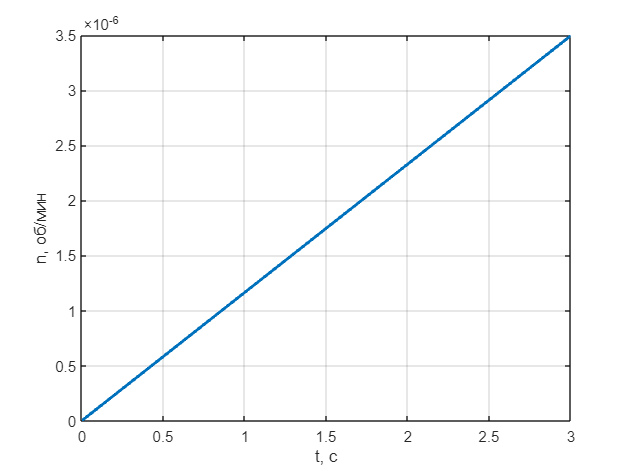

figure()
plot(t, w_mech_sim, 'LineWidth',2);
grid on
xlabel('t, c');
ylabel('n, об/мин');
xlim([0 3])

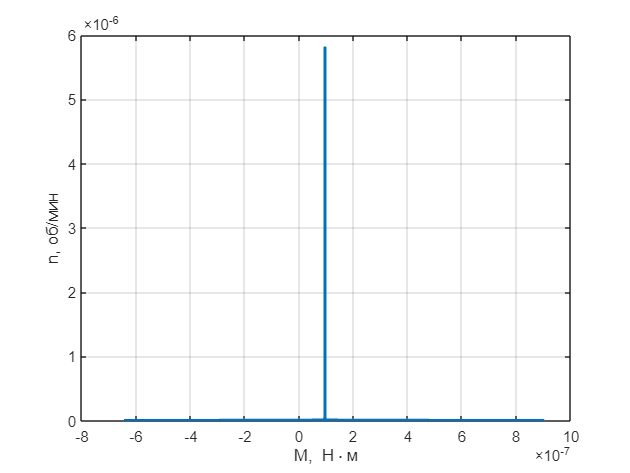

figure()
plot(M_mech_sim,w_mech_sim, 'LineWidth',2);
grid on
xlabel('M, Н\cdotм');
ylabel('n, об/мин');

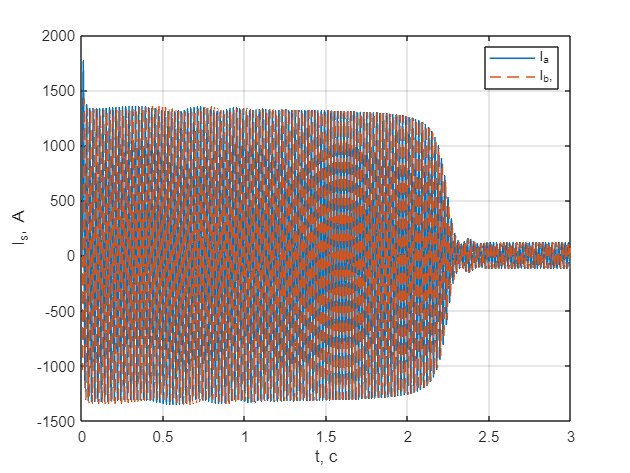

figure()
plot(t,Ia, 'LineWidth',1);
hold on
plot(t,Ib, 'LineWidth',1, 'LineStyle', '--');
grid on
xlabel('t, c');
ylabel('I_{s}, А');
legend("I_{a}", "I_{b},")
xlim([0 3])

ДИНАМИЧЕСКАЯ МОДЕЛЬ АД С КЗР

w_r_sim = out.sim.Data(:,1) * 30/pi; 
i_a_sim = out.sim.Data(:,2); 
t_sim = out.sim.Time;

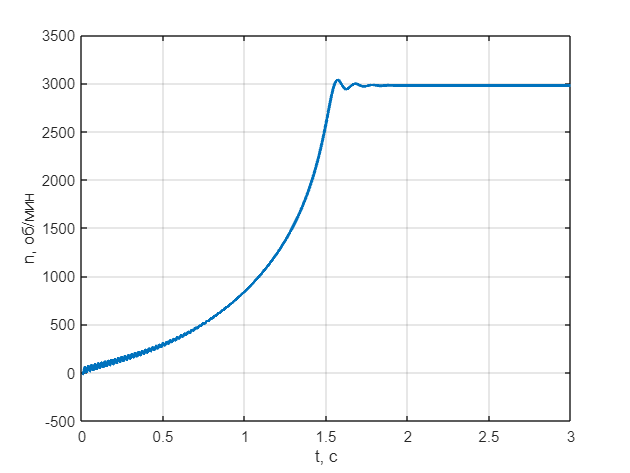

figure()
plot(t_sim,w_r_sim, 'LineWidth',2);
grid on
xlabel('t, c');
ylabel('n, об/мин');
xlim([0 3])

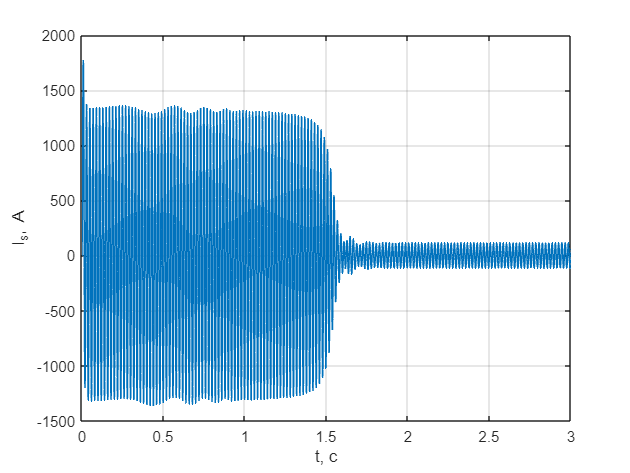

figure()
plot(t_sim,i_a_sim, 'LineWidth',1);
grid on
xlabel('t, c');
ylabel('I_{s}, А');
xlim([0 3])

SIMSCAPE

M_mech_sim_50 = out.mechanic.Data(:,1); 
w_mech_sim_50 = out.mechanic.Data(:,2) * 30/pi;
t = out.mechanic.Time;
Ia_50 = out.electric.Data(:,1);
Ib_50 = out.electric.Data(:,2);

M_mech_sim_75 = out.mechanic.Data(:,1); 
w_mech_sim_75 = out.mechanic.Data(:,2) * 30/pi;
t = out.mechanic.Time;
Ia_75 = out.electric.Data(:,1);
Ib_75 = out.electric.Data(:,2);

M_mech_sim_100 = out.mechanic.Data(:,1); 
w_mech_sim_100 = out.mechanic.Data(:,2) * 30/pi;
t = out.mechanic.Time;
Ia_100 = out.electric.Data(:,1);
Ib_100 = out.electric.Data(:,2);

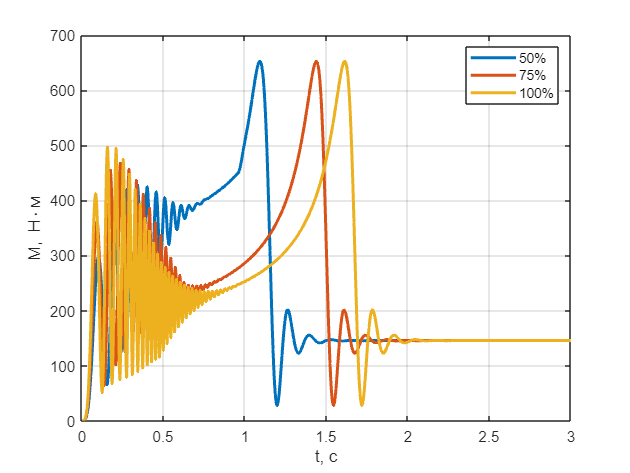

figure()
plot(t, M_mech_sim_50, 'LineWidth',2);
grid on
hold on
plot(t, M_mech_sim_75, 'LineWidth',2);
plot(t, M_mech_sim_100, 'LineWidth',2);
xlabel('t, c');
ylabel('M, Н\cdotм');
legend('50%', '75%', '100%')
xlim([0 3])

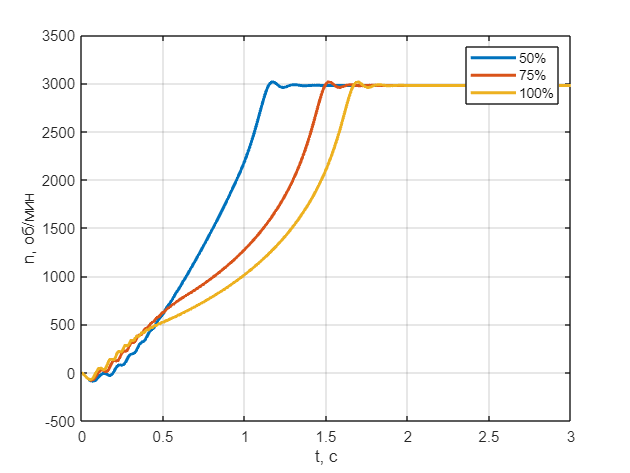

figure()
plot(t, w_mech_sim_50, 'LineWidth',2);
grid on
hold on
plot(t, w_mech_sim_75, 'LineWidth',2);
plot(t, w_mech_sim_100, 'LineWidth',2);
xlabel('t, c');
ylabel('n, об/мин');
legend('50%', '75%', '100%')
xlim([0 3])

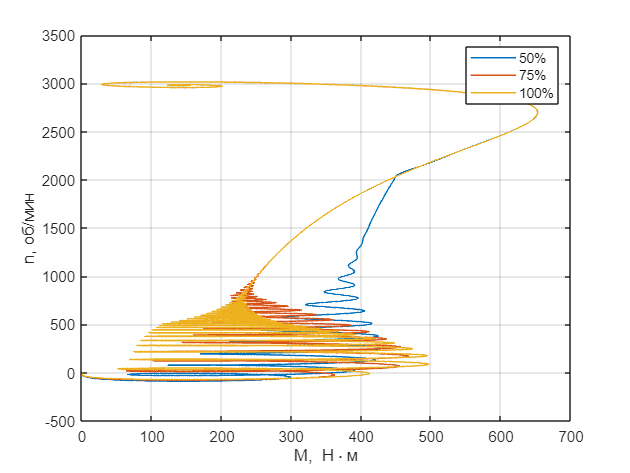

figure()
plot(M_mech_sim_50,w_mech_sim_50, 'LineWidth',1);
grid on
hold on
plot(M_mech_sim_75,w_mech_sim_75, 'LineWidth',1);
plot(M_mech_sim_100,w_mech_sim_100, 'LineWidth',1);
xlabel('M, Н\cdotм');
ylabel('n, об/мин');
legend('50%', '75%', '100%')

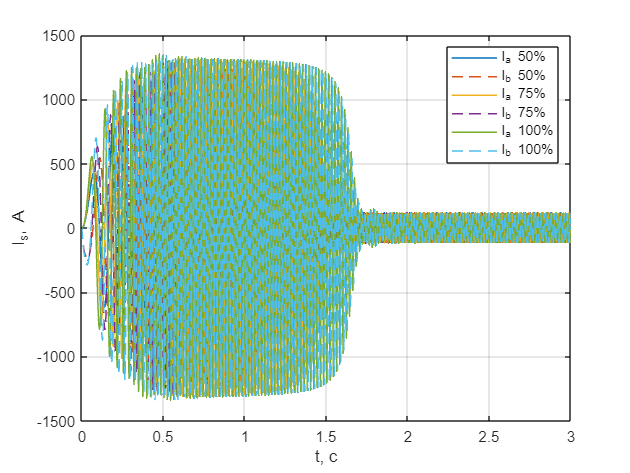

figure()
plot(t, Ia_50, 'LineWidth',1);
grid on
hold on
plot(t, Ib_50, 'LineWidth',1, 'LineStyle', '--');

plot(t, Ia_75, 'LineWidth',1);
plot(t, Ib_75, 'LineWidth',1, 'LineStyle', '--');

plot(t, Ia_100, 'LineWidth',1);
plot(t, Ib_100, 'LineWidth',1, 'LineStyle', '--');
xlabel('t, c');
ylabel('I_{s}, А');
legend('I_{a} 50%', 'I_{b} 50%', 'I_{a} 75%', 'I_{b} 75%', 'I_{a} 100%', 'I_{b} 100%')
xlim([0 3])

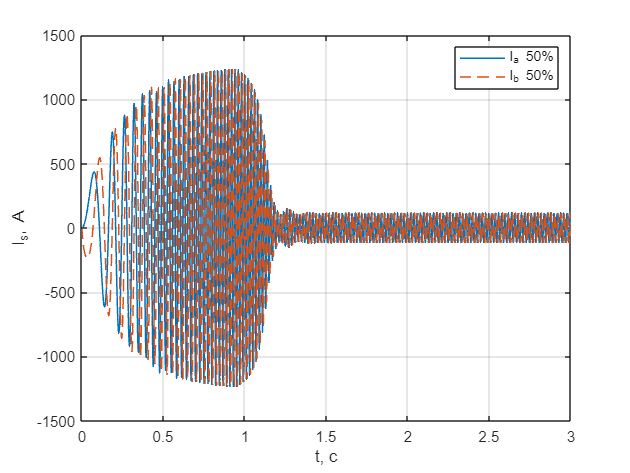

figure()
plot(t, Ia_50, 'LineWidth',1);
grid on
hold on
plot(t, Ib_50, 'LineWidth',1, 'LineStyle', '--');
xlabel('t, c');
ylabel('I_{s}, А');
legend('I_{a} 50%', 'I_{b} 50%')
xlim([0 3])

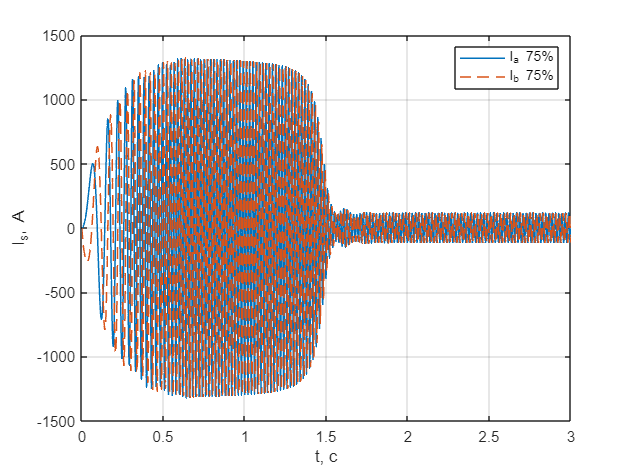

figure()
plot(t, Ia_75, 'LineWidth',1);
grid on
hold on
plot(t, Ib_75, 'LineWidth',1, 'LineStyle', '--');
xlabel('t, c');
ylabel('I_{s}, А');
legend('I_{a} 75%', 'I_{b} 75%')
xlim([0 3])

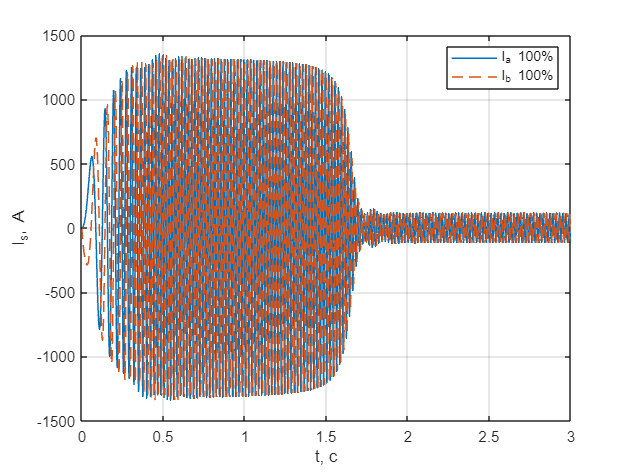

figure()
plot(t, Ia_100, 'LineWidth',1);
grid on
hold on
plot(t, Ib_100, 'LineWidth',1, 'LineStyle', '--');
xlabel('t, c');
ylabel('I_{s}, А');
legend('I_{a} 100%', 'I_{b} 100%')
xlim([0 3])